# Example 2.16: Product Failure and Guarantee

Note: this script reproduces Example 2.16 (Section 2.2.4) of **Statistics for Chemical Engineers**: lifetime of an adhesive with an average of 36 months. Victor Z UW-Madison, 2020 exponential failure adhesive material

clc; clear all; close all hidden;

## Model

average failure time

eta=3*12; % months

## Outcomes

generate outcomes

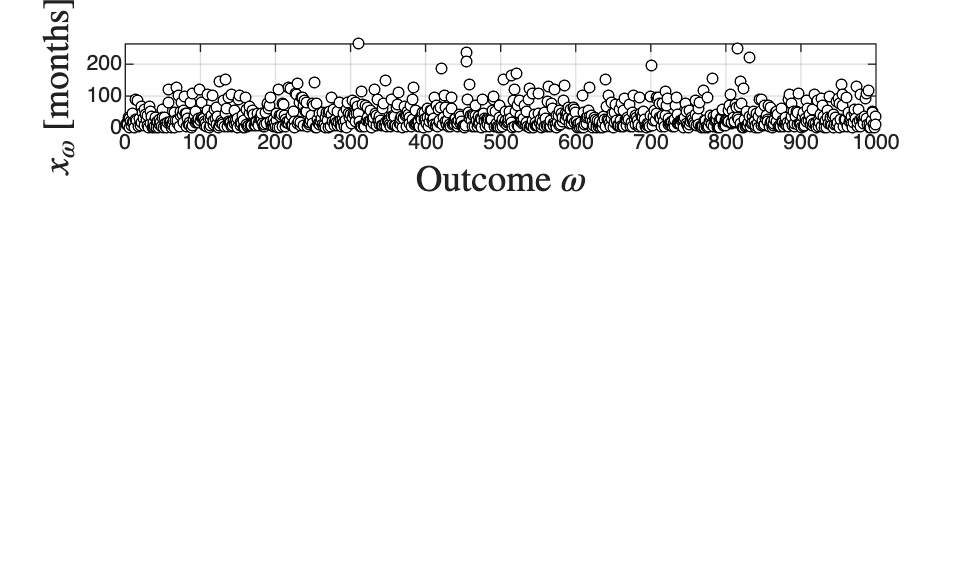

S=1000;
x=exprnd(eta,S,1);

subplot(3,1,1)
plot(x,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$ [months]','Interpreter','latex','FontSize',14)
grid on

## Pdf and cdf

empirical & theoretical pdf

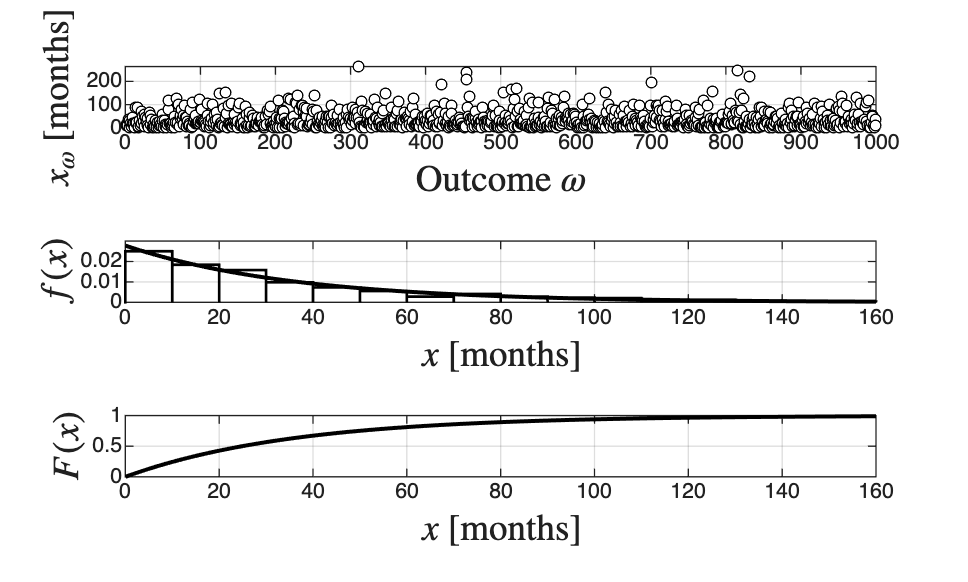

subplot(3,1,2)
xx=linspace(0,160);
plot(xx,exppdf(xx,eta),'black','LineWidth',1.5)
hold on
histogram(x,'BinWidth',10,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$x$ [months]','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
axis([0 160 0 0.03])
% theoretical cdf
subplot(3,1,3)
xx=linspace(0,160);
plot(xx,expcdf(xx,eta),'black','LineWidth',1.5)
hold on
xlabel('$x$ [months]','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
grid on
axis([0 160 0 1])

print -depsc ch2_exp_failure.eps

## Survival after 12 months

probability of surviving after 12 months

S=1-expcdf(12,eta)

S = 0.7165

## Note

As in the book, to survive 12 months with probability 0.95 the average lifetime must be 233 months: about 6.5 times longer than now.